# MATLAB Tutorial 3. Step Response

## 1. 전달함수 생성

clc; clear
% 전달함수 식의 계수로 전달함수 객체 생성
T = tf([1 4], [1 3 2])

T =
 
      s + 4
  -------------
  s^2 + 3 s + 2
 
연속시간 전달 함수입니다.



% 전달함수 수식 입력
s = tf('s');
G = (s+3)/((s+1)*(s+2))

G =
 
      s + 3
  -------------
  s^2 + 3 s + 2
 
연속시간 전달 함수입니다.



% 피드백 시스템의 전달함수
% H: feedback gain
H = 4;
F = feedback(G, H)

F =
 
      s + 3
  --------------
  s^2 + 7 s + 14
 
연속시간 전달 함수입니다.



## 2. 시스템의 응답 구하기

% 시스템 전달함수 정의
s=tf('s');                                     
G_s=4*(s+2)/(s*(s+3)*(s+7))

G_s =
 
        4 s + 8
  -------------------
  s^3 + 10 s^2 + 21 s
 
연속시간 전달 함수입니다.



% 단위 귀환 시스템의 전달함수
sys=feedback(G_s,1)

sys =
 
          4 s + 8
  -----------------------
  s^3 + 10 s^2 + 25 s + 8
 
연속시간 전달 함수입니다.



### 2.1 단위계단응답

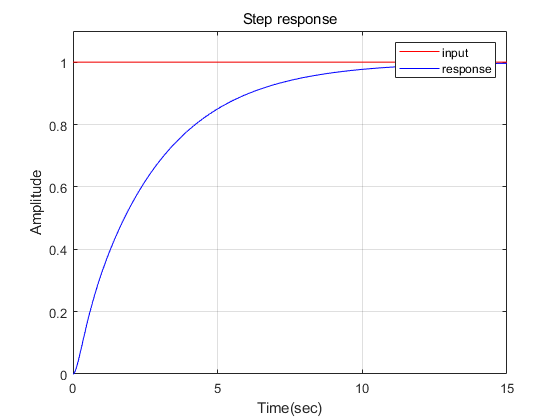

% 단위 계단 응답 계산 y=출력, t=시간
[y,t]=step(sys);
% 입력데이터 만들기: 출력시간의 길이만큼 1의 배열 생성
u=ones(size(t));

% 입력(u)과 출력(y) 그리기
plot(t,u,'r-', t,y,'b-')
axis([0 15 0 1.1])
xlabel('Time(sec)')
ylabel('Amplitude')
title('Step response')
legend('input', 'response')
grid

### 2.2 단위경사응답

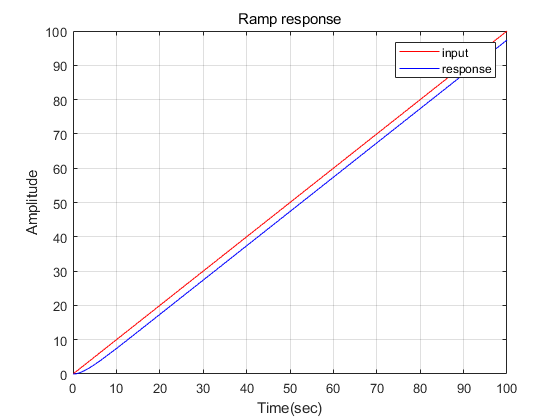

% 단위 램프 응답 계산 t=시간, u=입력, y=출력
t=0:0.1:100;
u=t;
[y,t]=lsim(sys,u,t);

% 입력(u)과 출력(y) 그리기
plot(t,u,'r-', t,y,'b-')
xlabel('Time(sec)')
ylabel('Amplitude')
title('Ramp response')
legend('input', 'response')
grid

### 2.3 단위포물선응답

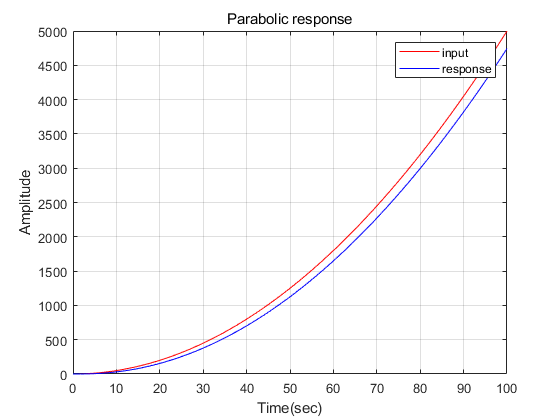

% 포물선 입력 응답 계산 t=시간, u=입력, y=출력
t=0:0.1:100;
u=0.5*t.*t;
[y,t]=lsim(sys,u,t);

% 입력(u)과 출력(y) 그리기
plot(t,u,'r-', t,y,'b-')
xlabel('Time(sec)')
ylabel('Amplitude')
title('Parabolic response')
legend('input', 'response')
grid

## 3. 시간응답 성능

교재 5장에 나오는 과도응답 성능을 계산

% 부족제동 시스템
s = tf('s');
M = 9/(s^2+3*s+9)

M =
 
        9
  -------------
  s^2 + 3 s + 9
 
연속시간 전달 함수입니다.



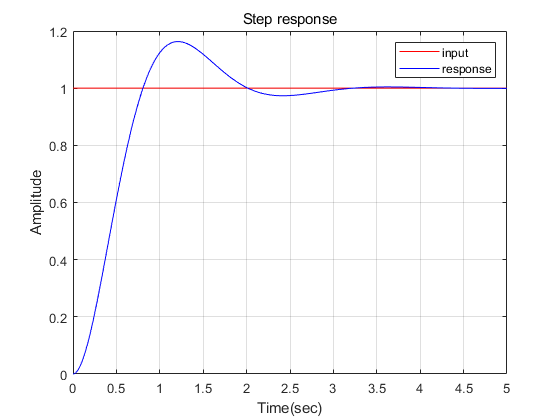

% 시스템의 단위 계단 응답 그리기
draw_step_response(M);

% 시스템 파라미터와 성능 계산
transient_response(M);

ans = "omega: 3.0000, zeta: 0.5000"

ans = "pole: 1.5000 +- j2.5981"

poles =   -1.5000 + 2.5981i
  -1.5000 - 2.5981i


ans = "pole: -1.5000 +- j2.5981"

Performance indices from stepinfo()


S = 다음 필드를 포함한 struct :
        RiseTime: 0.5463
    SettlingTime: 2.6920
     SettlingMin: 0.9315
     SettlingMax: 1.1629
       Overshoot: 16.2929
      Undershoot: 0
            Peak: 1.1629
        PeakTime: 1.1973


Manually computed performance indices


rise_time = 0.6833

settling_time = 2.6667

peak_time = 1.2092

over_shoot = 16.3034

## 4. 안정도

% 시스템 안정도 판별 (안정 시스템)
s = tf('s');
M1 = 12/(s^3+4*s^2+8*s+12)

M1 =
 
            12
  ----------------------
  s^3 + 4 s^2 + 8 s + 12
 
연속시간 전달 함수입니다.



stability_check(M1);

This system is determined to be STABLE by 'isstable()' function.


num =      0     0     0    12


den =      1     4     8    12


poles =   -2.6850 + 0.0000i
  -0.6575 + 2.0092i
  -0.6575 - 2.0092i


pole_real =    -2.6850
   -0.6575
   -0.6575


This system is STABLE. All poles are on the left side.


M2 = 3/(s^4+s^3+2*s^2+2*s+3)

M2 =
 
               3
  ---------------------------
  s^4 + s^3 + 2 s^2 + 2 s + 3
 
연속시간 전달 함수입니다.



stability_check(M2);

This system is determined to be UNSTABLE by 'isstable()' function.


num =      0     0     0     0     3


den =      1     1     2     2     3


poles =    0.4057 + 1.2928i
   0.4057 - 1.2928i
  -0.9057 + 0.9020i
  -0.9057 - 0.9020i


pole_real =     0.4057
    0.4057
   -0.9057
   -0.9057


This system is UNSTABLE. Some poles are NOT on the left side.


function transient_response(M)
[num,den] = tfdata(M);
num = num{1};
den = den{1};
omega = sqrt(den(3));
zeta = den(2) / 2 / omega;
sprintf("omega: %1.4f, zeta: %1.4f", omega, zeta)
repole = zeta * omega;
impole = omega * sqrt(1 - zeta^2);
sprintf("pole: %1.4f +- j%1.4f", repole, impole)
poles = roots(den)
sprintf("pole: %1.4f +- j%1.4f", real(poles(1)), imag(poles(1)))
% 과도응답 성능 계산
disp('Performance indices from stepinfo()')
S = stepinfo(M)
% 수동으로 계산
disp('Manually computed performance indices')
rise_time = (0.8 + 2.5*zeta) / omega
settling_time = 4 / repole
peak_time = pi / impole
over_shoot = exp(-pi*zeta/sqrt(1-zeta^2)) * 100
end


function draw_step_response(M)
Tfinal = 5;
t = 0:0.01:Tfinal;
y = step(M, t);
u = ones(size(t));
plot(t,u,'r-',t,y,'b-')
axis([0 Tfinal 0 1.2])
xlabel('Time(sec)')
ylabel('Amplitude')
title('Step response')
legend('input', 'response')
grid
end


function stability_check(M)
if isstable(M)
    disp("This system is determined to be STABLE by 'isstable()' function.")
else
    disp("This system is determined to be UNSTABLE by 'isstable()' function.")
end

[num,den] = tfdata(M);
num = num{1}
den = den{1}
poles = roots(den)
pole_real = real(poles)
if all(pole_real < 0)
    disp("This system is STABLE. All poles are on the left side.")
else
    disp("This system is UNSTABLE. Some poles are NOT on the left side.")
end
end